## Part3 - Analyzing real data

So far, we have done a lot of work on simluated data. We know how to:

- Preprocess the spike times into a spike count matrix;

- Create a Support Vector Machine classifier;

- Compute a surrogates distribution for this classifier.

Now, let's try to apply those tools to real data.

### The organization of the real data

We are going to use data from a similar task. A head-fixed mouse was trainned to differentiate between 2 sound stimuli. For each trial, one of the two stimulus would be played for 2 seconds (stimulus period) and then, after a 1-sec-window of silence (we call this the trace period), the animal would receive or not a reward (reward period), depending on wich sound was played. Because the stimuli and the reward periods do not overlap, we call this a trace-conditioning task. 

So now, in order to see the full extension of a trial, we are going to extract spikes from 1 second before the stimulus start (pre-stimulus period), to 4 seconds after it (2 s of stim, 1 s of trace and 1 s of reward periods).

### Loading the data

We first load the data, that is organized in the same way as our simulated data. 

clear all
load('real_data_example','spktimes','srate','stim_times','stim_type')


### Question 5

Redo the plot in question 4 using the real data. 

(Although this seems a long question, you should be able to reuse most of the code so far. However, remeber that the duration of the trials is different now, and that might require some modifications in the code..)

binwidth = 0.1; % in seconds (100 ms)
bins = 0:binwidth*srate:5*srate; %changed 4 into 5
bins=bins/srate;

n_cells=length(spktimes);
n_trials= length(stim_type);

spk_matrix = zeros(n_cells,n_trials,length(bins)-1);
for icell = 1:length(spktimes)
    
    spk = spktimes{icell};
    
    for itrial = 1:length(stim_times)
        idx = (spk>stim_times(itrial)-1 & spk<=stim_times(itrial)+3);
        
        spk_temp = spk(idx)-(stim_times(itrial)-1);
        
        count = histc(spk_temp,bins);
        
        % the last count is for values higher than the last bin edge, so we can discard it.
        count = count(1:end-1);
        
        spk_matrix(icell,itrial, :) = count;
        
    end
end
% let's define our time vector as the center of each bin
time_bins = bins(1:end-1)+binwidth/2;

% we also want the time 0 to be the moment of the stimulus
time_bins = time_bins -1;

bin_performances = [];
for b=1:length(time_bins)
    %train for bin:
    k=2;
    C = cvpartition(n_trials,'KFold',k);
    ibin=b;
    performance=[];
    for i=1:k
    % geting the training and test sets for the ith fold.
        trainingset = C.training(i);
        testset = C.test(i);
        bin_matrix = squeeze(spk_matrix(:,:,ibin));
        SVMModel = fitcsvm(bin_matrix(:,trainingset)',stim_type(trainingset),'KernelFunction','linear','Standardize',false);
        
        [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
        performance(i) = mean(predicted_type==stim_type(testset)');
    end
    bin_performances(b) = mean(performance);
    
end

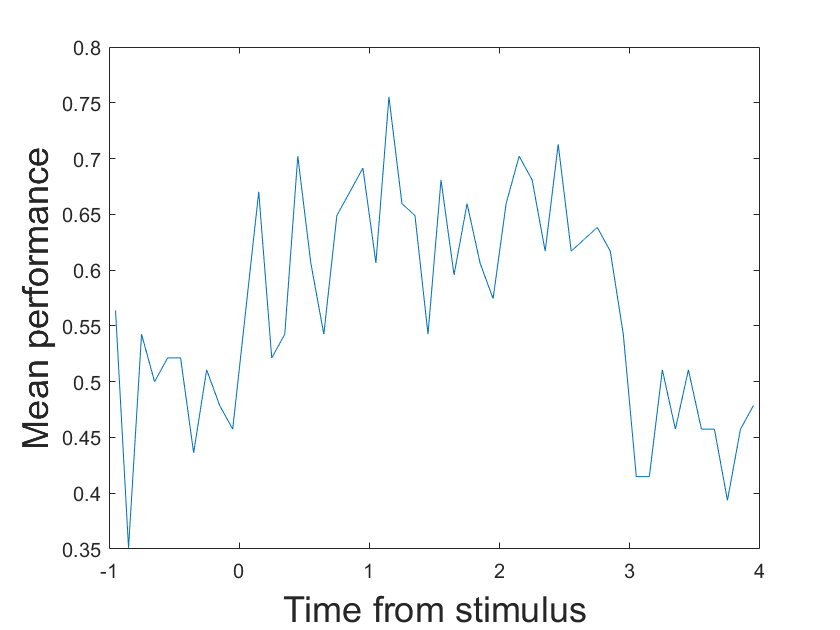

figure
plot(time_bins, bin_performances)
xlabel('Time from stimulus','FontSize',18)
ylabel('Mean performance','FontSize',18)

%computing surr for every bin:

means_surr = [];
stds_surr = [];
norm_performance = [];
for b=1:50
   ibin = b;
    
    % Computing surrogates
    n_surr = 100;
    mean_surr_performance_bin=zeros(1,n_surr);
    
    performances_for_every_surr = [];
    for isurr=1:n_surr
        
        % for each surrogate let's randomly shuffle the stim_type.
        [v, rand_order] = sort(rand(1,length(stim_type))); % this is a trick to get shuffled indexes
        shuffled_stim_type = stim_type(rand_order); % and then we use those indexes on the stim_type vector
        
        % Now we just compute the mean performance for this surrogate using the
        % shuffled labels (i.e., stim_type)
        performance_surr_bin=[];
        for i=1:k
            trainingset = C.training(i);
            testset = C.test(i);
            
            bin_matrix = squeeze(spk_matrix(:,:,ibin));
            SVMModel = fitcsvm(bin_matrix(:,trainingset)',shuffled_stim_type(trainingset),'KernelFunction','linear','Standardize',false);
            
            [predicted_type,score] = predict(SVMModel,bin_matrix(:,testset)');
            
        end
        performances_for_every_surr(isurr) = mean(predicted_type == stim_type(testset)');
    end
    max_values(b) = max(performances_for_every_surr);
    means_surr(b) = mean(performances_for_every_surr);
    stds_surr(b) = std(performances_for_every_surr);
   
end

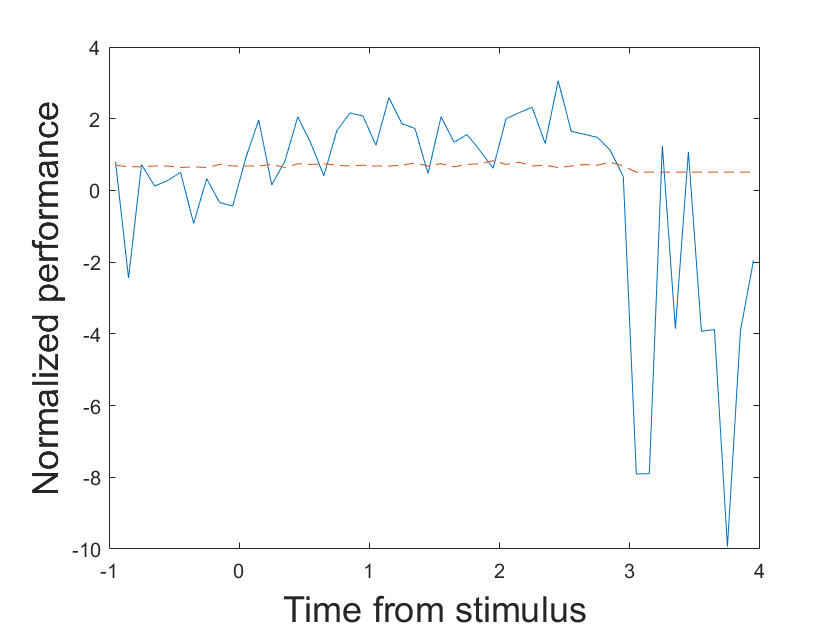

normalized_performance = (bin_performances - means_surr) ./ stds_surr;
max_values_normalized = (max_values - means_surr) ./stds_surr;
figure
plot(time_bins, normalized_performance)
hold on
plot(time_bins, max_values, '--')
xlabel('Time from stimulus','FontSize',18)
ylabel('Normalized performance','FontSize',18)

### Question 6

Coment on the result you found on question 5. What can you conclude from the decoding performance on each period (pre-stimulus, stimulus, trace and reward)? What do you think of the decoding performance of the trace period? Did you expect that? 

During the pre-stimulus period (-1 until 0 s) the performance is around/ below 0. This of course makes, sense because the cells haven't start firing because the stimulus was not present yet. Then, when the stimulus is present (from 0), the performance increases. This is nice to see, because the classifier has learned to respond to the stimulus. During the stimulus (0 until 2 seconds), the performance remains high. During the trace period (2 until 3 s), performance remains high for a bit more. I did not expect this. Some possible explanation could be that the animal keeps the stimulus (sound) in mind, until it receives the reward. This makes sense because than the animal can couple the stimulus to the reward (and thus learn something). 

While the reward is given, performance decreases extremely. 

### Bonus Question

Now that you know how to apply a surrogate/shuffling to analyze the statistical significance of a result, go back to assignment 1 and think of a way of doing this with the spatial information metric that you used there (Skagg's formula). What would be the best way to shuffle the data in order to compute each surrogate?

You can describe how you would do it here, or actually implement it (in python or matlab).